# Using Quaternion sentences 

Note:   - The 'arrow' option requires the function arrow3. find it at:  [https://www.mathworks.com/matlabcentral/fileexchange/14056-arrow3](https://www.mathworks.com/matlabcentral/fileexchange/14056-arrow3)

## 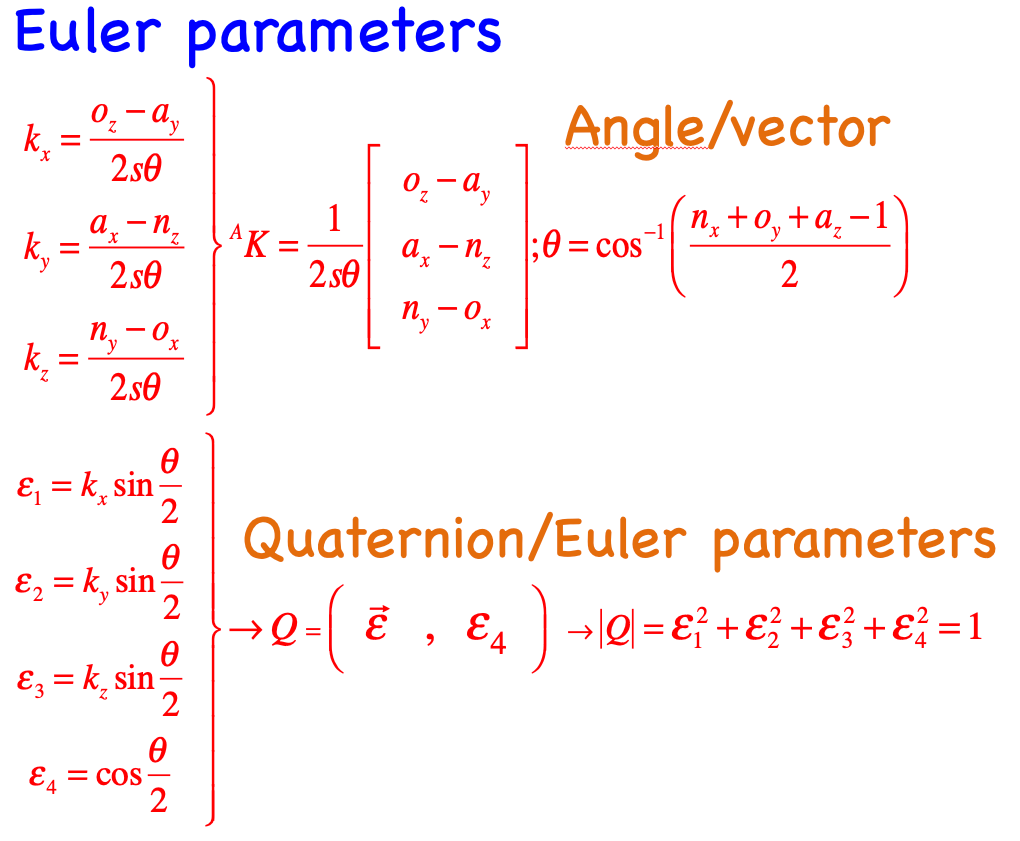

## Quaternion instances, examples

Rotation about z [0 0 1] a small angle $\theta =0\ldotp 1$

### Quaternion paramenters by hand

clear
theta=0.1

theta = 0.1000

e1=0

e1 = 0

e2=0

e2 = 0

e3=1*sin(theta/2)

e3 = 0.0500

e4=1*cos(theta/2)

e4 = 0.9988

### Quaternion instance using RTB

All yields the same result

q1 = UnitQuaternion(rotz(theta))

 
q1 = 
 
0.99875 < 0, 0, 0.049979 >
 


q2 = UnitQuaternion( rpy2tr(0, 0, theta))

 
q2 = 
 
0.99875 < 0, 0, 0.049979 >
 


q3 = UnitQuaternion.rpy(0,0,theta)

 
q3 = 
 
0.99875 < 0, 0, 0.049979 >
 


q4 = UnitQuaternion.angvec((theta), [0 0 1])

 
q4 = 
 
0.99875 < 0, 0, 0.049979 >
 


q5 = UnitQuaternion.eul([0 0 theta])

 
q5 = 
 
0.99875 < 0, 0, 0.049979 >
 


### Simple Operation

Rotating unitary vector [0 0 1] does not change the vector. It is like matrix multiplication

w=q4*[0 0 1]' 

w =      0
     0
     1


## Displaying enviroment

Given two Reference Frames $X^A$ and  $X^B$ find the Quaternion such that rotating $X^A$ yield $X^B$.

clear
eu1=[0.3 0.6 0.4]

eu1 =     0.3000    0.6000    0.4000


eu2=[0.1 0.2 0.3]

eu2 =     0.1000    0.2000    0.3000


XA=eul2r(eu1)

XA =     0.6112   -0.5792    0.5394
    0.5967    0.7849    0.1669
   -0.5201    0.2199    0.8253


XB=eul2r(eu2)

XB =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


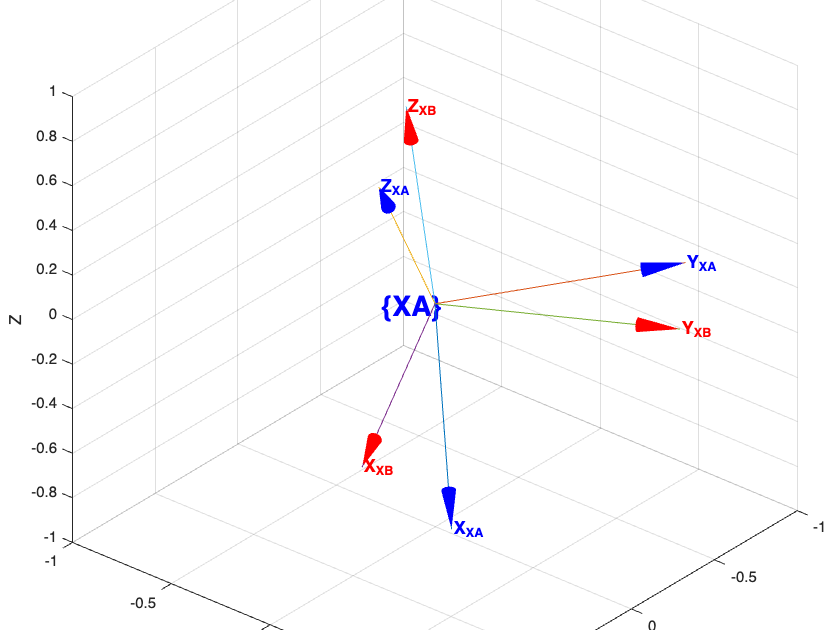



trplot(XA, ... %We plot the reference frame XA
    'frame', 'XA', ... 
    'color', 'b',...
    'arrow',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[130,30],...
    'width', 1.2)
hold on
trplot(XB, ... %We plot the reference frame XB
    'frame', 'XB', ... 
    'color', 'r',...
    'arrow',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[130,30],...
    'width', 1.2)
hold on

### Finding  ${}_B^AR$

R_B_A=XA'*XB

R_B_A =     0.8813    0.2850   -0.3771
   -0.2601    0.9585    0.1166
    0.3946   -0.0047    0.9188


Going FW/BW

XB_R=XA*R_B_A % Going FW in post multiplication

XB_R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


XB

XB =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


XA_R=XB*R_B_A' % Going BW in post multiplication

XA_R =     0.6112   -0.5792    0.5394
    0.5967    0.7849    0.1669
   -0.5201    0.2199    0.8253


XA

XA =     0.6112   -0.5792    0.5394
    0.5967    0.7849    0.1669
   -0.5201    0.2199    0.8253


###  ang/vec

[ang vec]=tr2angvec(R_B_A)

ang = 0.4964

vec =    -0.1273   -0.8102   -0.5722


Displaying the vector embeded in the quaternion

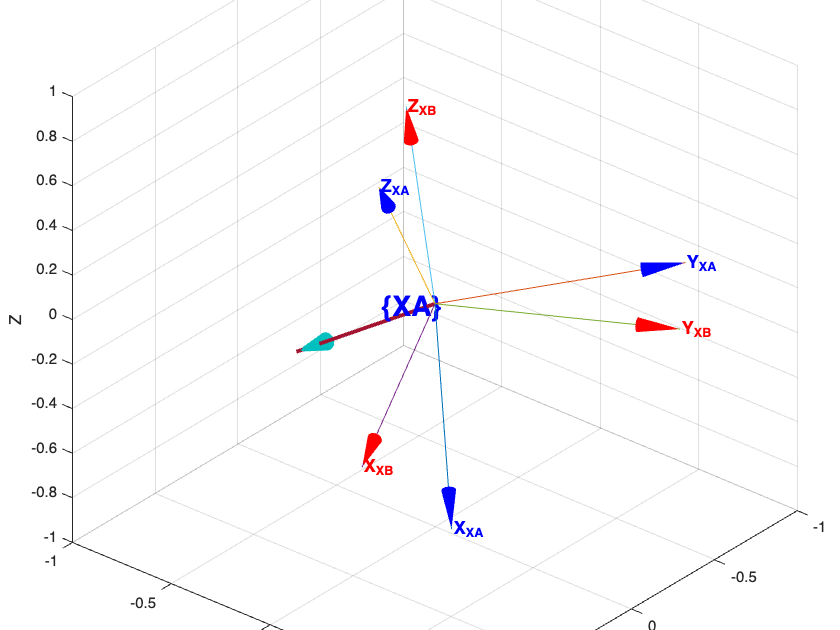

arrow3([0 0 0],vec, '2.5s',1.5)

### Animation buit in RTB

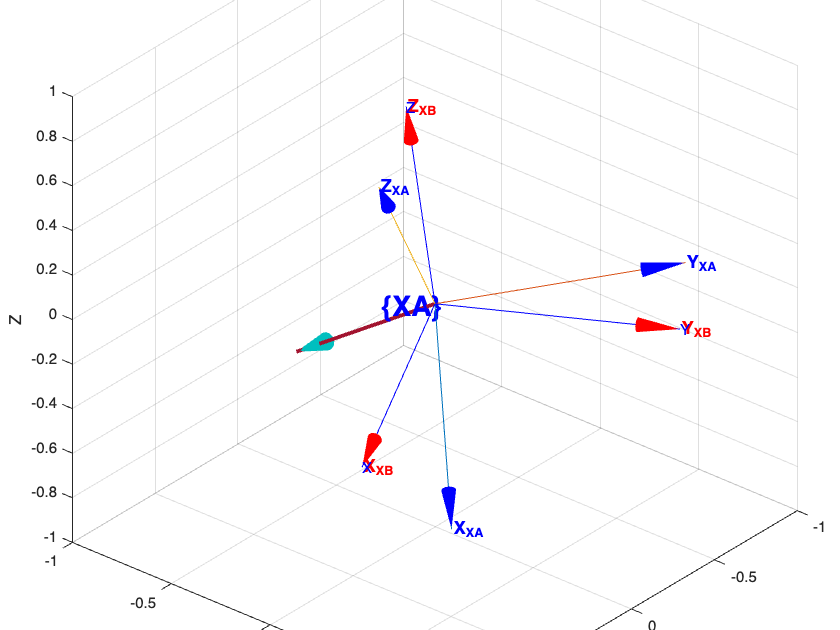

tranimate (XA,XB,20); % tranimate embeded quaternions

### Quaternion / Rotation matrix 

QA=UnitQuaternion.eul(eu1)

 
QA = 
 
0.89742 < 0.01477, 0.29515, 0.32758 >
 


XAq=QA.R

XAq =     0.6112   -0.5792    0.5394
    0.5967    0.7849    0.1669
   -0.5201    0.2199    0.8253


XA

XA =     0.6112   -0.5792    0.5394
    0.5967    0.7849    0.1669
   -0.5201    0.2199    0.8253


QB=UnitQuaternion.eul(eu2)

 
QB = 
 
0.97517 < 0.0099667, 0.099335, 0.19768 >
 


XBq=QB.R

XBq =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


XB

XB =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


RBAq=inv(QA)*QB

 
RBAq = 
 
0.96936 < -0.031263, -0.19902, -0.14058 >
 


Q=UnitQuaternion(R_B_A) 

 
Q = 
 
0.96936 < -0.031263, -0.19902, -0.14058 >
 


RBAq.R

ans =     0.8813    0.2850   -0.3771
   -0.2601    0.9585    0.1166
    0.3946   -0.0047    0.9188


R_B_A

R_B_A =     0.8813    0.2850   -0.3771
   -0.2601    0.9585    0.1166
    0.3946   -0.0047    0.9188


XAA=Q

 
XAA = 
 
0.96936 < -0.031263, -0.19902, -0.14058 >
 


### Interpolation / animating

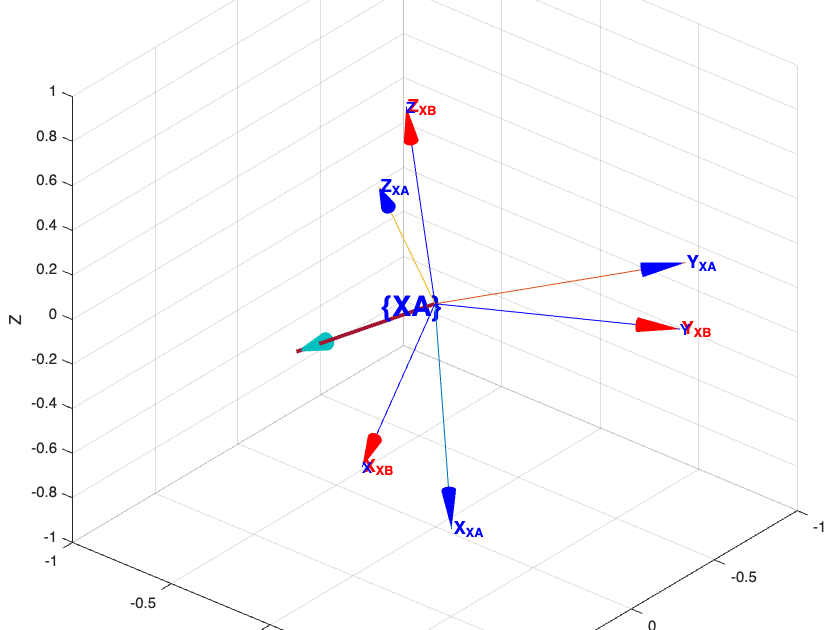

q=interp(QA,QB,[0:49]'/49) ;
%animate(q)
q.animate